computer=getenv('computername');
if computer=='NITHIN-SURFACE'
    pfisrDataFileNameStr =...
            'C:\Users\Nithin\Documents\GitHub\energy-height-conversion\Tools\Projects\Paper 1\Data\Ground\pfisr_data_26_Mar_2008.mat';
else 
    pfisrDataFileNameStr =...
        '/home/nithin/Documents/git-repos/energy-height-conversion/Tools\Projects\Paper 1\Data\Ground\PFISR_Energy_Spectra/Data/Ground/pfisr_data_26_Mar_2008.mat';
end
load (pfisrDataFileNameStr);


## Plotting

thisTime1 = '26 Mar 2008 11:25';
thisTime2 = '26 Mar 2008 11:30';
thisTime3 = '26 Mar 2008 11:30';
p=plot_1D_time_slice(pfisrBeamAvg.energySpectraVickery.time,pfisrBeamAvg.energySpectraVickery.energyBin,pfisrBeamAvg.energySpectraVickery.energyFlux,thisTime1,3); 
hold on;
q=plot_1D_time_slice(pfisrBeamAvg.energySpectraVickery.time,pfisrBeamAvg.energySpectraVickery.energyBin,pfisrBeamAvg.energySpectraVickery.energyFlux,thisTime2,3); 
hold off;

timeNo1=find_time(pfisrBeamAvg.energySpectraVickery.time, thisTime1);
timeNo2=find_time(pfisrBeamAvg.energySpectraVickery.time, thisTime2);

medianNo1 = find_median_energy(diff_to_cumu_flux(pfisrBeamAvg.energySpectraVickery.energyFlux(:,timeNo1),pfisrBeamAvg.energySpectraVickery.energyBin));
medianNo2 = find_median_energy(diff_to_cumu_flux(pfisrBeamAvg.energySpectraVickery.energyFlux(:,timeNo2),pfisrBeamAvg.energySpectraVickery.energyBin));

pfisrBeamAvg.energySpectraVickery.energyBin(medianNo1)/1000

ans = 3.8491

pfisrBeamAvg.energySpectraVickery.energyBin(medianNo2)/1000

ans = 2.9247

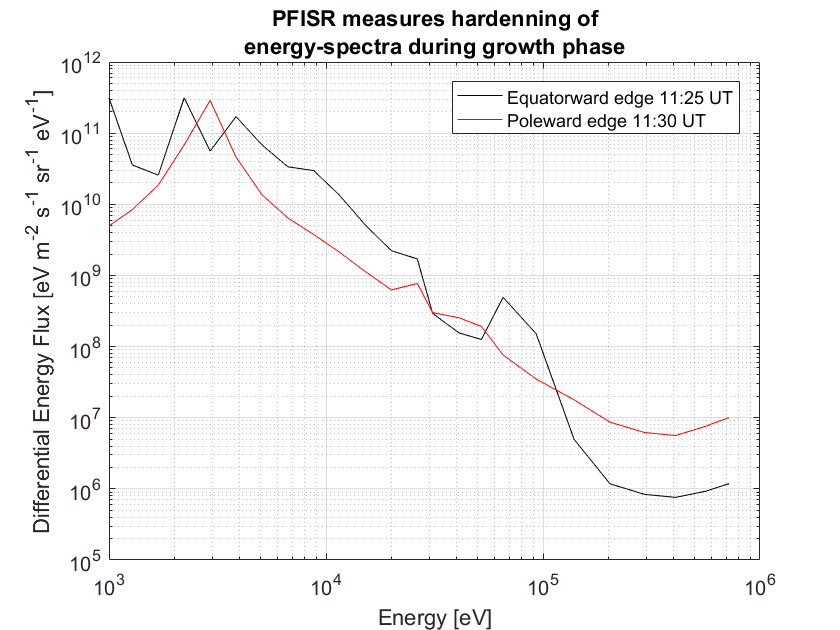


p.Color = 'k';
q.Color = 'r';
set(gca,'XLim',[10^3 10^6]);
legend('Equatorward edge 11:25 UT','Poleward edge 11:30 UT');
title({'PFISR measures hardenning of','energy-spectra during growth phase'});